# Homework 8

## Problem 5.1: Frequency estimation using Pisarenko's method

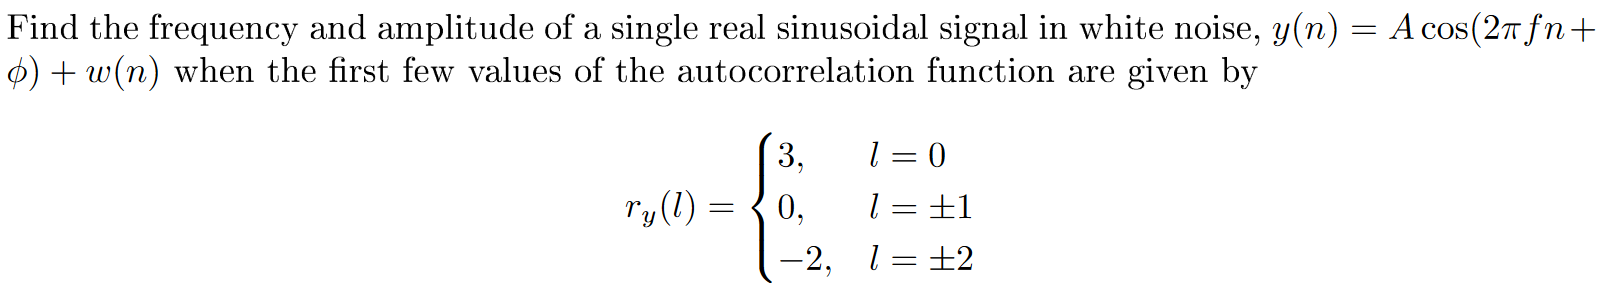

## Problem 5.2: Pisarenko

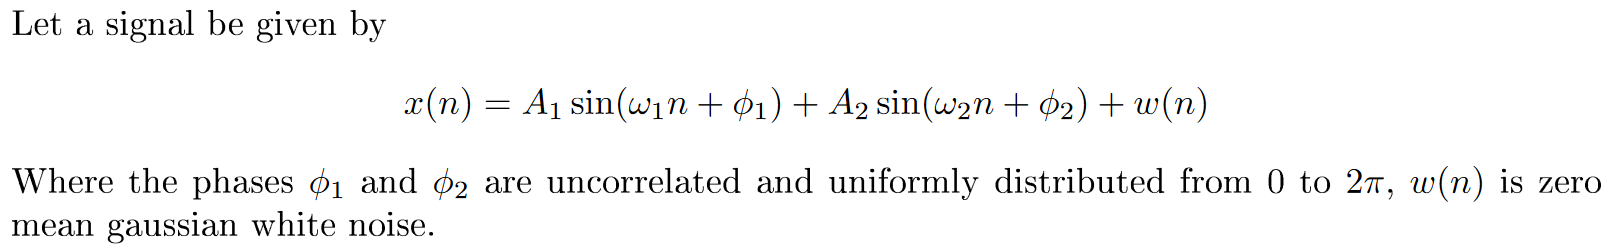

### 1) Calculate the autocorrelation function

### 2) Choose appropriate values for the amplitudes and frequencies and for the noise power

### 3) Calculate the eigenvalues of the autocorrelation matrix as a function of its size and compare with your expectation

### 4) Use the Pisarenko method to calculate the spectrum and compare with the expected results

## Problem 5.3: Frequency resolution of the Pisarenko method  

*In this problem the goal is to investigate the frequency resolution of the Pisarenko method. We will use your two-sinusoids-in-white-noise model from the previous problem:*

### 1) Create two realisations, use the Pisarenko method to compute the spectrum and comment on the stability of the method

***a) Create a number of short realizations, i.e. N=64 or N=128 with different initial phases.***

***b) Calculate the  autocorrelation matrices of the realizations.***

***c) Comment on the stability of the Pisarenko method***

### 2) Can shifts in frequency be measured?

*Create a number of short realizations where one of the frequencies is shifted 1% up or down. Can this shift in frequency be measured?  *

### 3) How small a frequency shift can you measure with a sequence length of *N*=128?

## Problem 5.4: Pisarenko and coloured noise

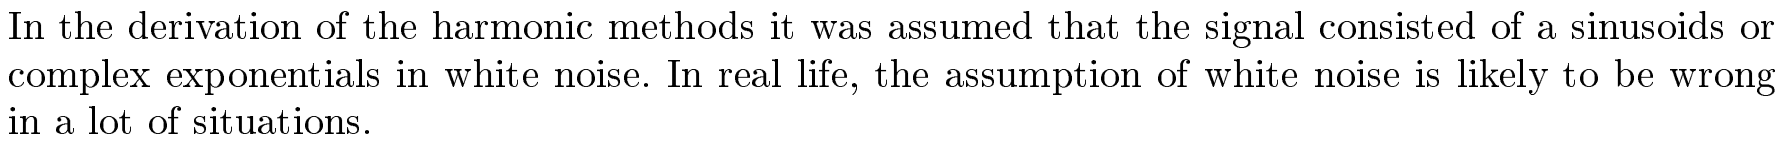

### 1) Create a MATLAB model of a sinusoidal signal in white, slightly coloured and very coloured noise.

### 2) Compare the eigenvalues of the autocorrelation matrix for the three different scenarios.  

### 3) Calculate the Pisarenko spectra and discuss whether Pisarenko is useful when the noise is coloured.

## Problem 5.5: Pisarenko, wrong choise of eigenvector

*In example 14.5.1 from the note the autocorrelation matrix for a process consisting of a single sinusoid in additive white noise is given as  *

        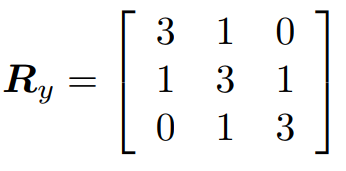

*The example proceeds to find *$f_1 =\frac{1}{8}$

### 1) How does the use of a wrong eigenvalue influence the solution?

*Repeat the example, but use the two other eigenvalues as starting points. How does the use of a wrong eigenvalue influence the solution?*

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{yy}}$

r_yy = [3, 1, 0];
R_yy = toeplitz(r_yy)
% Choose which eigenvalues is used for the calculations.
% The eigenvalues are sorted in increasing order, so
% the first eigenvalue is the smallest.
chosen_eig_idx = 1;


***Step 2:*** Find the minimum eigenvalue and the corresponding eigenvector. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

[eig_vecs, D] = eig(R_yy);
eig_vals = diag(D);

R_yy =      3     1     0
     1     3     1
     0     1     3



% The variance of the noise corresponds to the minimum eigenvalue
eig_val_min = eig_vals(chosen_eig_idx)

Using the smallest eigenvalue, we should get:

        

% Get the eigenvector corresponding to the minimum eigenvalue
eig_vec_min = eig_vecs(:,chosen_eig_idx);

% Ensure that a_0 = 1 (this is by definition)
eig_vec_min = eig_vec_min / eig_vec_min(1)

If the smallest eigenvalue is used we would get $a_0 =1$, $a_1 =-1\ldotp 4142$, $a_2 =1$

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in (14.5.4). This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        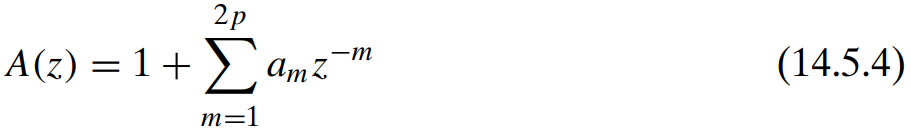

z = roots(eig_vec_min)

eig_val_min = 1.5858

So we have $z_1 =0\ldotp 7071+0\ldotp 7071j$ and $z_2 =0\ldotp 7071-0\ldotp 7071j$

Note that $\left|z_1 \right|=\left|z_2 \right|=1$ so poles are on the unit circle:

% norm(z(1)), norm(z(2))
% Verify that the poles are on the unit circle
zplane(1, eig_vec_min')

In general, the $z$ is defined as follows:

        
$$z=Ae^{\mathrm{j2}\pi f} =A\left\lbrack \mathrm{cos}\left(2\pi f\right)+j\;\mathrm{sin}\left(2\pi f\right)\right\rbrack$$


Recall that $\angle z=2\pi f$ and $f=\frac{\angle z}{2\pi }$ because of the definition of the complex number $z$:

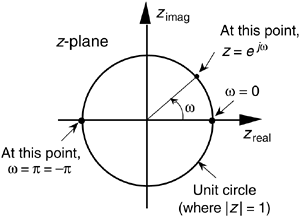

Since the two $z$ quantities that we found are on the unit circle, their magnitude $A=1$.

We also found that two pair of $z$s are complex conjucates of one another. So we only use one of them to compute the frequency:

f1 = abs(angle(z(2))) / (2*pi)

eig_vec_min =     1.0000
   -1.4142
    1.0000


**Step 4:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        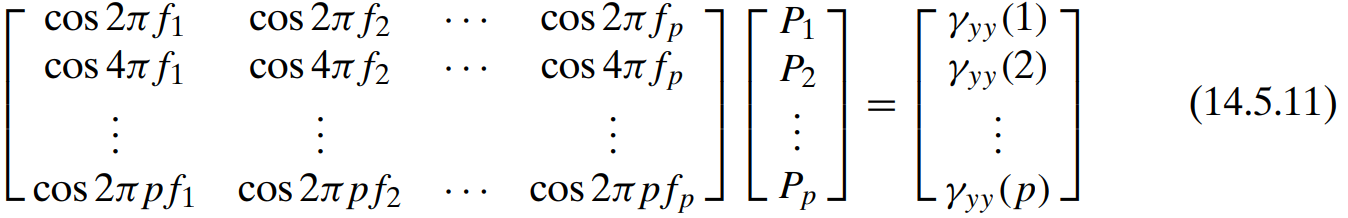

Since we only have one frequency, the equation becomes:

        $\mathrm{cos}\left(2\pi f_1 \right)P_1 =\gamma_{\mathrm{yy}} \left(1\right)$ where $\gamma_{\textrm{yy}} \left(1\right)$ is the second autocorrelation value:

We want to find $P_1$:  

        
$$P_1 =\frac{\gamma_{\textrm{yy}} \left(1\right)}{\cos \left(2\pi f_1 \right)}$$
  

P1 = r_yy(2) / cos(2*pi*f1)

z =    0.7071 + 0.7071i
   0.7071 - 0.7071i


From section 14.5.1, we are given:

        
$$P_i =\frac{A_i^2 }{2}$$


This allows us to estimate the amplitude $A_i$ given $P_i$:

        
$$A_i =\sqrt{2P_i }$$


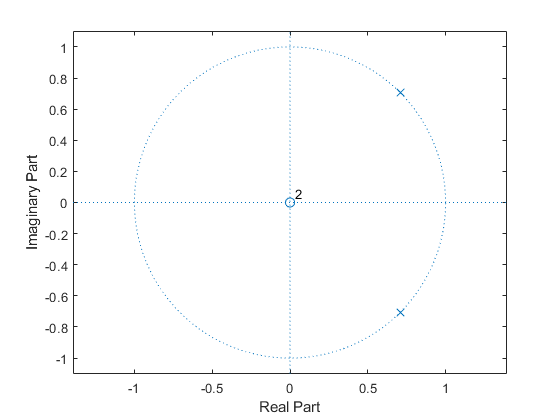

f1 = 0.1250

P1 = 1.4142

A1 = 1.6818

A1 = sqrt(2*P1)

## Exam 2012, Problem 3: PSD Estimation

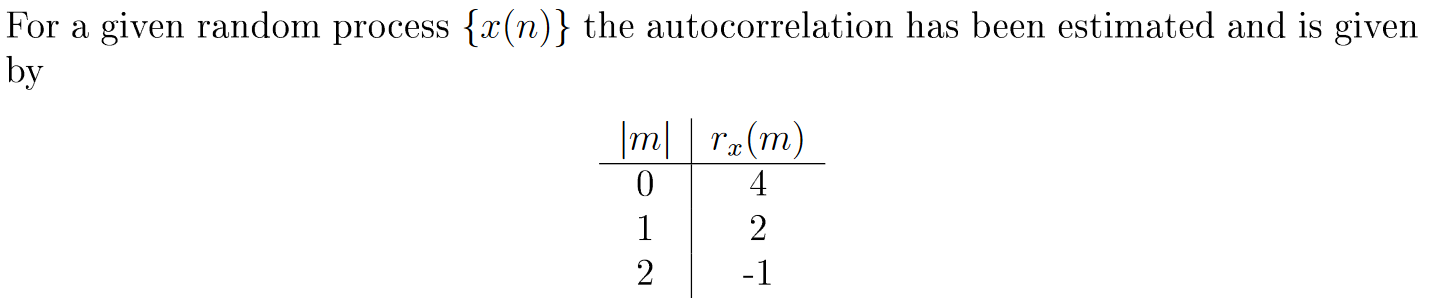

### 1) Estimate PSD assuming sinusoidal white noise

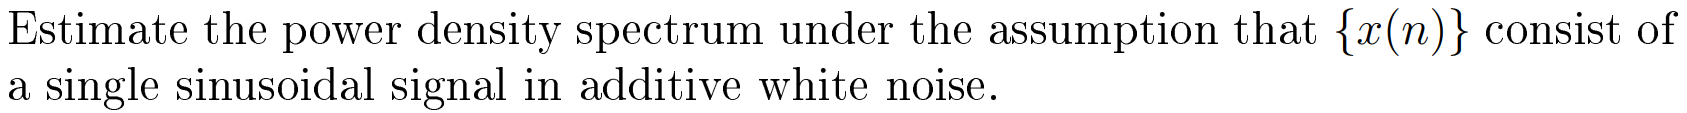

### 2) Estimate PSD assuming MA(2) process